%% Load Image
img = imread('./Data/cameraman.jpg');

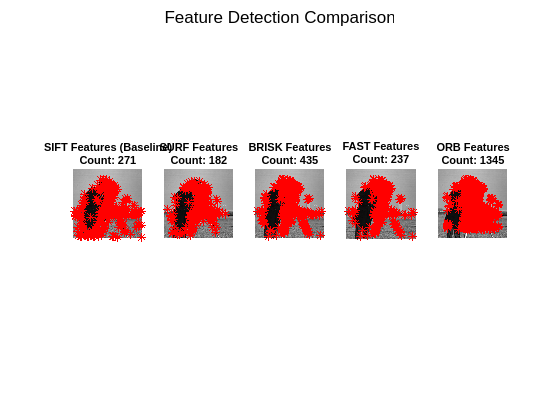

% Figure 1 - Features Detection Comparison
figure('Name', 'Feature Detection Comparison', 'NumberTitle', 'off');

% 1. SIFT (baseline)
subplot(1, 5, 1);
imshow(imgGray); hold on;
siftPoints = detectSIFTFeatures(imgGray);
numberPoints_SIFT = siftPoints.Count;
plot(siftPoints.Location(:,1), siftPoints.Location(:,2), 'r*');
title(sprintf('SIFT Features (Baseline)\nCount: %d', numberPoints_SIFT));
hold off;

% 2. SURF
subplot(1, 5, 2);
imshow(imgGray); hold on;
surfPoints = detectSURFFeatures(imgGray);
numberPoints_SURF = surfPoints.Count;
plot(surfPoints.Location(:,1), surfPoints.Location(:,2), 'r*');
title(sprintf('SURF Features\nCount: %d', numberPoints_SURF));
hold off;

% 3. BRISK
subplot(1, 5, 3);
imshow(imgGray); hold on;
briskPoints = detectBRISKFeatures(imgGray);
numberPoints_BRISK = briskPoints.Count;
plot(briskPoints.Location(:,1), briskPoints.Location(:,2), 'r*');
title(sprintf('BRISK Features\nCount: %d', numberPoints_BRISK));
hold off;

% 4. FAST
subplot(1, 5, 4);
imshow(imgGray); hold on;
fastPoints = detectFASTFeatures(imgGray);
numberPoints_FAST = fastPoints.Count;
plot(fastPoints.Location(:,1), fastPoints.Location(:,2), 'r*');
title(sprintf('FAST Features\nCount: %d', numberPoints_FAST));
hold off;

% 5. ORB
subplot(1, 5, 5);
imshow(imgGray); hold on;
orbPoints = detectORBFeatures(imgGray);
numberPoints_ORB = orbPoints.Count;
plot(orbPoints.Location(:,1), orbPoints.Location(:,2), 'r*');
title(sprintf('ORB Features\nCount: %d', numberPoints_ORB));
hold off;

sgtitle('Feature Detection Comparison');

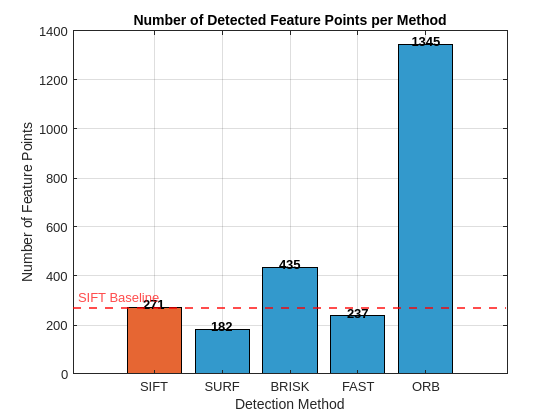

% Figure 2 - Points Count Comparison
figure('Name', 'Points Count Comparison');

methods = {'SIFT', 'SURF', 'BRISK', 'FAST', 'ORB'};
counts  = [numberPoints_SIFT, numberPoints_SURF, numberPoints_BRISK, ...
            numberPoints_FAST, numberPoints_ORB];

b = bar(counts, 'FaceColor', 'flat');
% Highlight SIFT bar in a distinct colour as baseline
b.CData(1,:) = [0.9 0.4 0.2];   % orange for SIFT
b.CData(2,:) = [0.2 0.6 0.8];
b.CData(3,:) = [0.2 0.6 0.8];
b.CData(4,:) = [0.2 0.6 0.8];
b.CData(5,:) = [0.2 0.6 0.8];

set(gca, 'XTickLabel', methods);
xlabel('Detection Method');
ylabel('Number of Feature Points');
title('Number of Detected Feature Points per Method');
grid on;

% Annotate bars with counts
for i = 1:length(counts)
    text(i, counts(i) + max(counts)*0.01, num2str(counts(i)), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% Add baseline reference line at SIFT count
yline(numberPoints_SIFT, '--r', 'SIFT Baseline', ...
    'LabelHorizontalAlignment', 'left', 'LineWidth', 1.5);

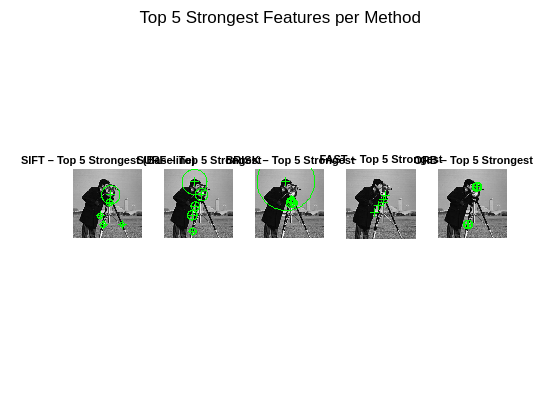

% Figure 3 - Top 5 Strongest Features
figure('Name', 'Top 5 Strongest Features');

subplot(1, 5, 1);
imshow(imgGray); hold on;
plot(selectStrongest(siftPoints, 5));
title('SIFT – Top 5 Strongest (Baseline)');

subplot(1, 5, 2);
imshow(imgGray); hold on;
plot(selectStrongest(surfPoints, 5));
title('SURF – Top 5 Strongest');

subplot(1, 5, 3);
imshow(imgGray); hold on;
plot(selectStrongest(briskPoints, 5));
title('BRISK – Top 5 Strongest');

subplot(1, 5, 4);
imshow(imgGray); hold on;
plot(selectStrongest(fastPoints, 5));
title('FAST – Top 5 Strongest');

subplot(1, 5, 5);
imshow(imgGray); hold on;
plot(selectStrongest(orbPoints, 5));
title('ORB – Top 5 Strongest');

sgtitle('Top 5 Strongest Features per Method');